clc;
clear all;

# Two Dimensional Eikonal Equation using 5th order WENO Fast Sweep algorithm

So after the failure of my first attempt to replicate the result, here I am trying to understand the new algorithm to solve the eikonal equation for a hypothetical two dimensional problem.

% Grid
Nx = 400;
Ny = 200;
Lx = 100;
Ly = 50;

dx = Lx / Nx;
dy = Ly / Ny;
h = 0;
if dx == dy
    h = dx;
end

x = linspace(0, Lx, Nx);
y = linspace(0, Ly, Ny);
[X, Y] = meshgrid(x, y);

INFINITE = 10^2;
eta = 10^-6;
error_eta = 10^-9;

% To track the error for each iterations
iteration_error = [];

% Total Time
t_total = 0.9;

## Initial Condtion

% Initial Condition (Gaussian Blob)

xc = 15;     % center x
yc = 25;     % center y
sigma = 5;   % width
rho_gauss = 0.05*exp( -((X-xc).^2 + (Y-yc).^2) / (2*sigma^2) ) + 0.45;

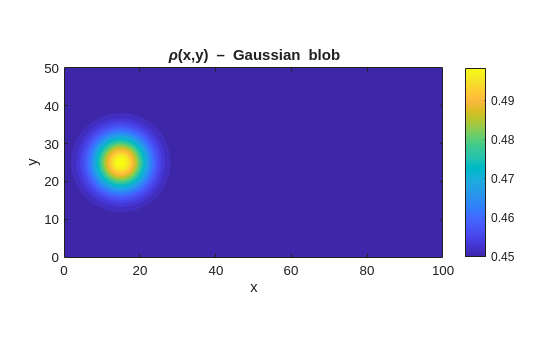

% Lets say there is no obstacle on the way
obstacle = false(Ny, Nx);
% obstacle(80:120,200:240) = true;
rho_gauss(obstacle) = 0;

figure(1); clf
contourf(X, Y, rho_gauss, 30, 'LineColor', 'none');
colorbar
axis equal tight
xlabel('x'); ylabel('y');
title('\rho(x,y) – Gaussian blob');

And with this density i would like to solve the eikonal equation using 5th order WENO algorithm. And the equation that was defined in the paper will require us to calculate the cost function first and here is how it needs to be defined

                         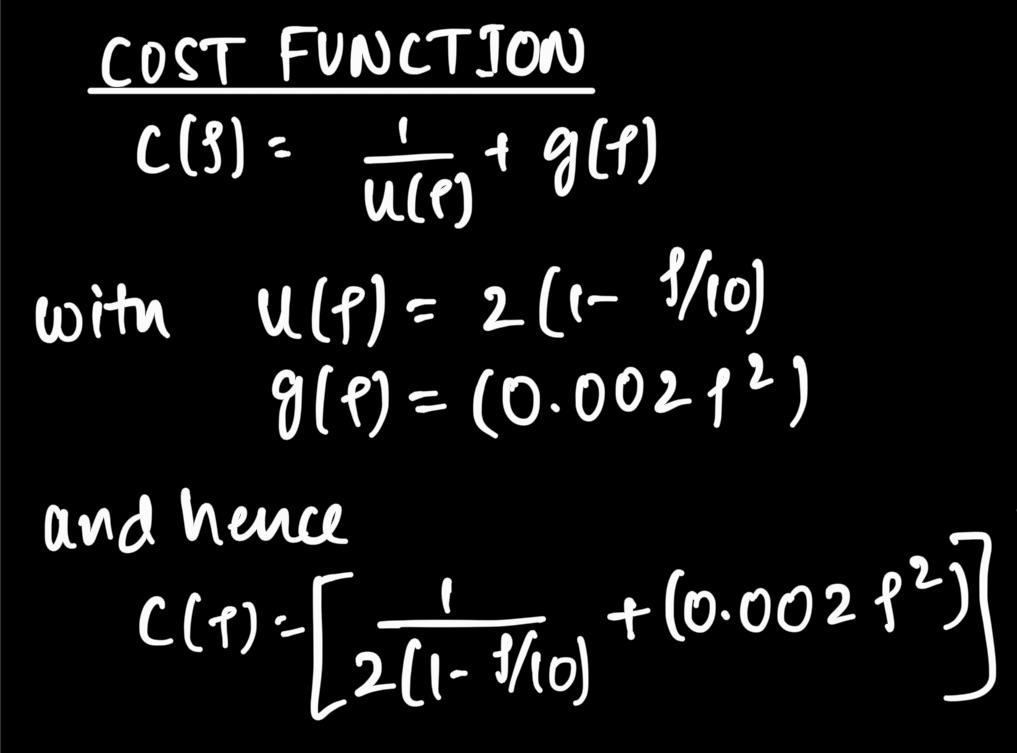

And hence to calculate this first we will calcuate the values of velocity and discomfort and then calculate the cost function

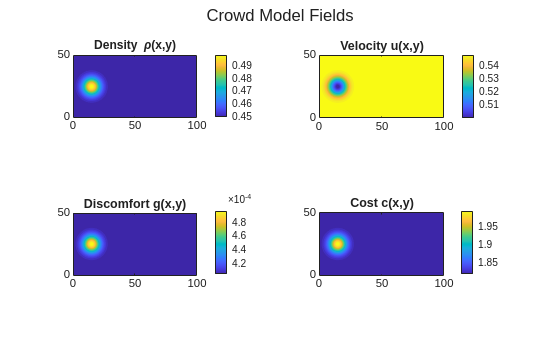

% Velocity
u = 1 - rho_gauss;
u = max(u, 1e-6);

% Discomfort
g = 0.002 * rho_gauss.^2;

% Cost
c = 1./u + g;


figure(1); clf

%---------------- Density ----------------%
subplot(2,2,1)
contourf(X, Y, rho_gauss, 30, 'LineColor','none')
colorbar
axis equal tight
title('Density \rho(x,y)')

%---------------- Velocity ----------------%
subplot(2,2,2)
contourf(X, Y, u, 30, 'LineColor','none')
colorbar
axis equal tight
title('Velocity u(x,y)')

%---------------- Discomfort ----------------%
subplot(2,2,3)
contourf(X, Y, g, 30, 'LineColor','none')
colorbar
axis equal tight
title('Discomfort g(x,y)')

%---------------- Cost ----------------%
subplot(2,2,4)
contourf(X, Y, c, 30, 'LineColor','none')
colorbar
axis equal tight
title('Cost c(x,y)')

sgtitle('Crowd Model Fields')

And now is the implementation of 5th order Fast sweep algorithm

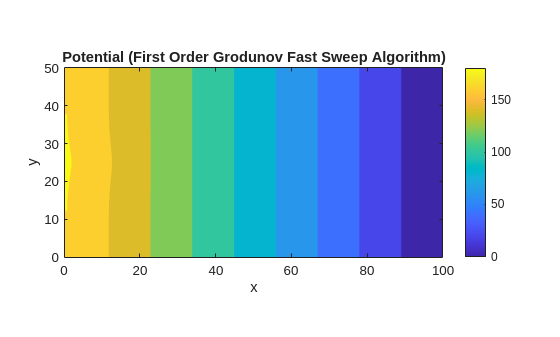

% Returns the phi values at the current time step
phi_first_order = First_order_Godunov_Fast_Sweep_Algorithm(c,dx,Nx,Ny,obstacle,INFINITE);

figure;
contourf(X, Y, phi_first_order, 'LineColor', 'none');
colorbar;
axis equal tight;
title('Potential (First Order Grodunov Fast Sweep Algorithm)');
xlabel('x'); ylabel('y');

And now I will be using this as my initial gues in the WENO algorithm

phi = weno_fastsweep(c,dx,Nx,Ny,obstacle,eta,error_eta,INFINITE,phi_first_order,iteration_error);

Iteration = 0 Error = 3673254.8785740258
Iteration = 1 Error = 17.1183245110
Iteration = 2 Error = 19.3295516845
Iteration = 3 Error = 18.4544833621
Iteration = 4 Error = 15.9496445910
Iteration = 5 Error = 13.3309782250
Iteration = 6 Error = 10.5447498056
Iteration = 7 Error = 8.0890626960
Iteration = 8 Error = 6.6323967979
Iteration = 9 Error = 7.1765350905
Iteration = 10 Error = 9.2946877956
Iteration = 11 Error = 8.7488598541
Iteration = 12 Error = 7.8413278658
Iteration = 13 Error = 6.5932225747
Iteration = 14 Error = 5.1646507428
Iteration = 15 Error = 3.7381067511
Iteration = 16 Error = 2.4536432785
Iteration = 17 Error = 1.4470515435
Iteration = 18 Error = 0.7228709812
Iteration = 19 Error = 0.2168446664
Iteration = 20 Error = 0.0342590723
Iteration = 21 Error = 0.0069354854
Iteration = 22 Error = 0.0016544673
Iteration = 23 Error = 0.0005695735
Iteration = 24 Error = 0.0002316465
Iteration = 25 Error = 0.0000997947
Iteration = 26 Error = 0.0000427779
Iteration = 27 Error = 0.0

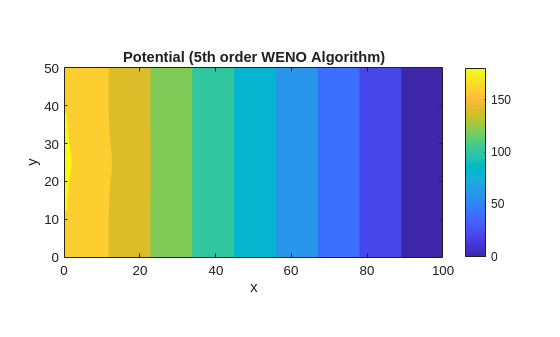

figure;
contourf(X, Y, phi, 'LineColor', 'none');
colorbar;
axis equal tight;
title('Potential (5th order WENO Algorithm)');
xlabel('x'); ylabel('y');

## First order Godunov Fast Sweep Algorithm (Older Version)

This is the algorithjm that is first order and was deisgned in last semeter. The solution that is obtained form this will be used as the initial condition for the WEO algorithm. This is done as said in the paper. The part of paper that says this is given below:

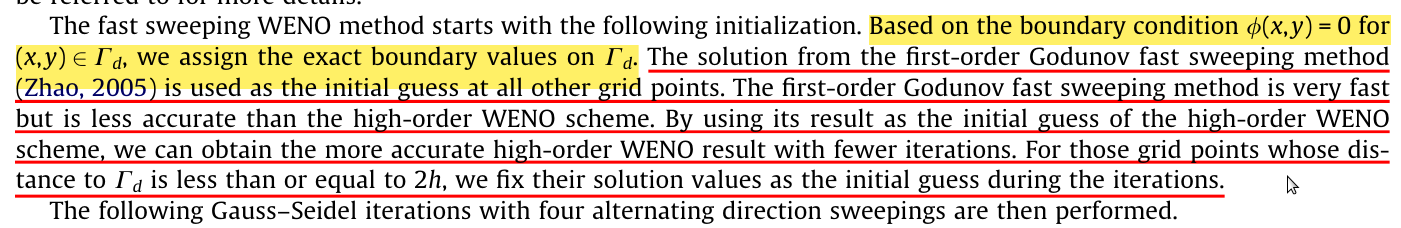

And I have found two important information form the underlines of text. They are that initial condition has to be taken to be taken to be taken from First order Godunov fast sweep, and the next condition is that the grid points present two point near the boundary has to kept as it is. And this makes it very clear to talk about the fifth order scheme, becayuse to calculate the value of phi at i would mean I will have to use the value of phi at ( i-2 ), ( i-1 ), i, ( i+1 ), ( i+2 ). And here in this implmenetation I have not taken any ghost points.

function phi = First_order_Godunov_Fast_Sweep_Algorithm(c,h,Nx_dash,Ny_dash,obstacle_dash,INFINITE)
    %---------------------------------------------
    % Initialization
    %---------------------------------------------
    phi = INFINITE*ones(Ny_dash, Nx_dash);    % Initial potential field
    phi(:,Nx_dash) = 0;             % Exit Boundary

    % Set phi inside obstacle to Inf
    phi(obstacle_dash) = INFINITE;

    %---------------------------------------------
    % Fast Sweeping Iterations
    %---------------------------------------------
    for sweep = 1:200
        % === Sweep 1
        for i = 2:Nx_dash-1
            for j = 2:Ny_dash-1
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
        end
        % === Sweep 2
        for i = Nx_dash-1:-1:2
            for j = 2:Ny_dash-1
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
        end
        % === Sweep 3
        for i = Nx_dash-1:-1:2
            for j = Ny_dash-1:-1:2
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
        end
       % === Sweep 4
       for i = 2:Nx_dash-1
            for j = Ny_dash-1:-1:2
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
       end

       phi(:,1) = phi(:,2);                % Right
       phi(1, :) = phi(2, :);              % Top
       phi(Ny_dash, :) = phi(Ny_dash-1,:);% Bottom

    end
    
end


% Subfunction: Update one grid point using Godunov scheme

function phi = update_phi(phi, invf, i, j, dx)
    a = min(phi(j, i-1), phi(j, i+1)); % x-direction neighbors
    b = min(phi(j-1, i), phi(j+1, i)); % y-direction neighbors
    f = invf(j, i); % Local inverse speed
    if abs(a - b) >= f * dx
        phi(j, i) = min(a, b) + f * dx;
        else
            inside = 2 * (f * dx)^2 - (a - b)^2;
        if inside >= 0
            phi(j, i) = (a + b + sqrt(inside)) / 2;
        end
    end
end

## WENO FAST SWEEP

Now that the code has successfully converged,it deserves a proper explanation. And here it is. So the program starts by initializing the value that are obtained form the first order Godunov solution that was programme din last semester. Due to the algorithm being non linear it was important to be careful when assigning the initial condition. I first made the 

### Important

There is an error in the papaer. And it is that the sign of the equlity has to be the other way around. **This was the reason I was gettiing the value of phi to be equal to be imaginary**. But now that it is clear, I am seeing the algorithm working and it is doing pretty good. Solutioin could be seen above

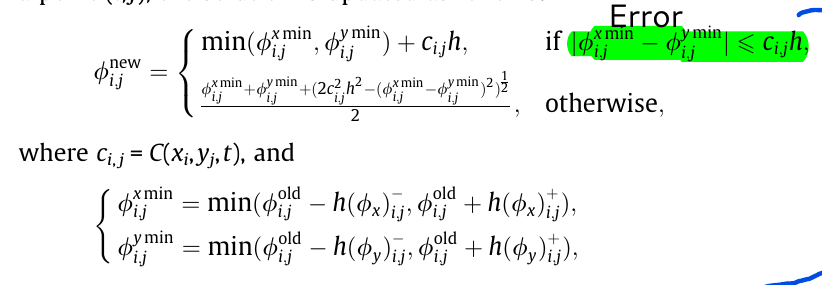

function phi = weno_fastsweep(c,h,Nx_dash,Ny_dash,obstacle_dash,eta,error_eta,INFINITE,initial_guess,iteration_error)
    % Phi is intialised with infinity
    phi = initial_guess;
    phi_old = INFINITE * ones(size(phi));

    % Iterations
    iterations = 0;
    loop_safety = 0;

    % Exit
    phi(:,Nx_dash) = 0;

    % Iterations
    while (sum(abs(phi(:)-phi_old(:))) > error_eta && loop_safety<100)

        fprintf("Iteration = %d ",iterations);
        err = sum(abs(phi(:)-phi_old(:)));
        fprintf("Error = %0.10f\n",err);

        phi_old = phi;
        iterations = iterations + 1;
        iteration_error(iterations) = err;
        loop_safety = loop_safety + 1;

        for sweep = 1:4
            switch sweep
                case 1 
                    ix = 3:1:Nx_dash-2; jy = 3:1:Ny_dash-2;
                case 2 
                    ix = 3:1:Nx_dash-2; jy = Ny_dash-2:-1:3;
                case 3 
                    ix = Nx_dash-2:-1:3; jy = 3:1:Ny_dash-2;
                case 4 
                    ix = Nx_dash-2:-1:3; jy = Ny_dash-2:-1:3;
            end

            

            for i = ix
                for j = jy
                    %if the point is outside the obstacle
                    if(~obstacle_dash(j,i))
                        %------------Calcualting the phix_min---------_%

                        r_back = (eta + (phi(j,i) - 2*phi(j,i-1) + phi(j,i-2))^2)/(eta + (phi(j,i+1) - 2*phi(j,i) + phi(j,i-1))^2);
                        r_front = (eta + (phi(j,i) - 2*phi(j,i+1) + phi(j,i+2))^2)/(eta + (phi(j,i+1) - 2*phi(j,i) + phi(j,i-1))^2);
    
                        % Calculate the w
                        w_front = 1/(1+2*(r_front^2));
                        w_back = 1/(1+2*(r_back^2));
    
                        % Dell phi by Dell x plus and minus
                        phix_minus = (1-w_back)*((phi(j,i+1)-phi(j,i-1))/(2*h)) + w_back*((3*phi(j,i) - 4*phi(j,i-1) + phi(j,i-2))/(2*h));
                        phix_plus = (1-w_front)*((phi(j,i+1)-phi(j,i-1))/(2*h)) + w_front*((-3*phi(j,i)+4*phi(j,i+1)-phi(j,i+2))/(2*h));
                        
                        
                        phix_min = min((phi(j,i) - h*phix_minus),(phi(j,i) + h*phix_plus));
                        
                        %-----------calculating the phiy_min---------%

                        r_back = (eta + (phi(j,i) - 2*phi(j-1,i) + phi(j-2,i))^2) / (eta + (phi(j+1,i) - 2*phi(j,i) + phi(j-1,i))^2);
                        r_front = (eta + (phi(j,i) - 2*phi(j+1,i) + phi(j+2,i))^2) / (eta + (phi(j+1,i) - 2*phi(j,i) + phi(j-1,i))^2);
    
                        % Calculate the w
                        w_front = 1 / (1 + 2*(r_front^2));
                        w_back = 1 / (1 + 2*(r_back^2));
    
                        % Dell phi by Dell x plus and minus
                        phiy_minus = (1-w_back) * ((phi(j+1,i)-phi(j-1,i))/(2*h)) + w_back * ((3*phi(j,i) - 4*phi(j-1,i) + phi(j-2,i))/(2*h));
                        phiy_plus = (1-w_front) * ((phi(j+1,i) - phi(j-1,i))/(2*h)) + w_front * ((-3*phi(j,i) + 4*phi(j+1,i) - phi(j+2,i))/(2*h));
                        
                        
                        phiy_min = min((phi(j,i) - h*phiy_minus), (phi(j,i) + h*phiy_plus));

                        if abs(phix_min - phiy_min) >= c(j,i)*h
                            phi(j,i) = min(phiy_min,phix_min) + c(j,i)*h;
                        else
                            phi(j,i) = ((phix_min + phiy_min) + (2*(c(j,i)*h)^2 - (phix_min - phiy_min)^2)^0.5)/2;
                        end
                    % If the point is inside the obstacle
                    else 
                        phi(j,i) = INFINITE;
                    end
                end
            end

            %------Extrapolation------%

            % Bottom edge %
            %phi(2,:) = phi(3,:);
            %phi(1,:) = phi(3,:);
            % Top edge %
            %phi(Ny_dash,:) = phi(Ny_dash-2,:);
            %phi(Ny_dash-1,:) = phi(Ny_dash-2,:);
            % Right edge %
            %phi(:,Nx_dash-1) = phi(:,Nx_dash-2);
            % Left edge %
            %phi(:,2) = phi(:,3);
            %phi(:,1) = phi(:,3);
        end   
    end
end

## Main Solver

rho = rho_gauss;

%-----------MAIN SOLVER------------%
t = 0; 
step = 0; % For plotting at regular interval

while t< t_total
    % Computing Cost For the density rho
    speed = 1-rho;
    discomfort = 0.002 * rho_gauss.^2;
    cost = 1./speed + discomfort;

    %-- Calculate Initial Phi guess using Lower order Fast Sweep
    phi_first_order = First_order_Godunov_Fast_Sweep_Algorithm(cost,h,Nx,Ny,obstacle,INFINITE);
   %-- Calculate The final phi using higher ordfer scheme and above intial guess 
    phi = weno_fastsweep(cost,h,Nx,Ny,obstacle,eta,error_eta,INFINITE,phi_first_order,iteration_error);

    %--Calculate the Components of Velocity
    [phi_x, phi_y] = gradient(phi, h, h); % partial derivatives of phi in x and y
    mag_phi = sqrt(phi_x.^2 + phi_y.^2);
    mag_phi = max(mag_phi, eta);          % To be safe with denominator
    for i = 1:1:Nx
        for j = 1:1:Ny
            x_velocity(j,i) = speed(j,i) * (phi_x(j,i))/mag_phi(j,i);
            y_velocity(j,i) = speed(j,i) * (phi_y(j,i))/mag_phi(j,i);
        end
    end

    % Updating the delta_t with proper CFL condition (Wiki Pedia)
    u_max = max(abs(x_velocity(:)));
    v_max = max(abs(y_velocity(:)));
    dt = CFL / ( u_max/h + v_max/h + 1e-12 );



    % Now Updating the density
    rho = upwind_update(rho, x_velocity, y_velocity, dx, dy, dt);

    %--Ploting the rho_next;
    if mod(step, 1) == 0
    
        % --- 1D slice ---
        figure(7);
        clf;
        plot(x, rho, '-');
        grid on;
        xlabel('x');
        ylabel('\rho');
        title(sprintf('Density at Ly = 25 (Ny = 100 , Centerline), t = %.2f', t));
        ylim([0 1]);
    
        % --- 2D contour ---
        %figure(6);
        %contourf(x, y, phi, 20, 'LineColor', 'none');
        %colorbar;
        %clim([0 1]);
        %title(sprintf('Density (rho) at t = %.2f', t));
        %xlabel('x'); ylabel('y');
        %axis equal tight;
    
        drawnow;
    end


    % Substituting back the rho value \
    rho = rho_next; 

    % Updating the time
    t = t + dt;
end

Iteration = 0 Error = 3673254.8785740258
Iteration = 1 Error = 17.1183245110
Iteration = 2 Error = 19.3295516845
Iteration = 3 Error = 18.4544833621
Iteration = 4 Error = 15.9496445910
Iteration = 5 Error = 13.3309782250
Iteration = 6 Error = 10.5447498056
Iteration = 7 Error = 8.0890626960
Iteration = 8 Error = 6.6323967979
Iteration = 9 Error = 7.1765350905
Iteration = 10 Error = 9.2946877956
Iteration = 11 Error = 8.7488598541
Iteration = 12 Error = 7.8413278658
Iteration = 13 Error = 6.5932225747
Iteration = 14 Error = 5.1646507428
Iteration = 15 Error = 3.7381067511
Iteration = 16 Error = 2.4536432785
Iteration = 17 Error = 1.4470515435
Iteration = 18 Error = 0.7228709812
Iteration = 19 Error = 0.2168446664
Iteration = 20 Error = 0.0342590723
Iteration = 21 Error = 0.0069354854
Iteration = 22 Error = 0.0016544673
Iteration = 23 Error = 0.0005695735
Iteration = 24 Error = 0.0002316465
Iteration = 25 Error = 0.0000997947
Iteration = 26 Error = 0.0000427779
Iteration = 27 Error = 0.0

Unrecognized function or variable 'CFL'.

## Upwinding Scheme

function rho_new = upwind_update(rho, vx, vy, dx, dy, dt) 
    [Ny, Nx] = size(rho);
    % Boundary Condition
    for j = 2 : Ny-1
        rho(j,1) = 0;
        rho(j,Nx) = rho(j,Nx-1);
    end
    for i = 2 : Nx-1
        rho(1,i) = 0;
        rho(Ny,i) = 0;
    end
    % Initalizing the flux values to be zero intially. 
    flux_xp = zeros(Ny,Nx);
    flux_xm = zeros(Ny,Nx);
    flux_yp = zeros(Ny,Nx);
    flux_ym = zeros(Ny,Nx); 
    % Upwinding scheme implementation 
    for j = 2 : Ny-1 
        for i = 2 : Nx-1 
            % x-direction fluxes
            flux_xp(j,i) = max(vx(j,i),0)*rho(j,i)   + min(vx(j,i),0)*rho(j,i+1);
            flux_xm(j,i) = max(vx(j,i),0)*rho(j,i-1) + min(vx(j,i),0)*rho(j,i);

            % y-direction fluxes
            flux_yp(j,i) = max(vy(j,i),0)*rho(j,i)   + min(vy(j,i),0)*rho(j+1,i);
            flux_ym(j,i) = max(vy(j,i),0)*rho(j-1,i) + min(vy(j,i),0)*rho(j,i);
        end 
    end 
    % Finite difference equation obtained form discritization of continuity equation. 
    rho_new = rho - (dt/dx) * (flux_xp - flux_xm) - (dt/dy) * (flux_yp - flux_ym);
end